# ECEN5463 | HW 1

Collin Thornton

## Problem 1

### 1-1 $\dot{\;x} =4x^2 -16$

syms x

f = 4*x^2 - 16;

sol = solve(f==0);
eq_points = sol

$$eq\_points = \left(\begin{array}{c} -2\\ 2 \end{array}\right)$$

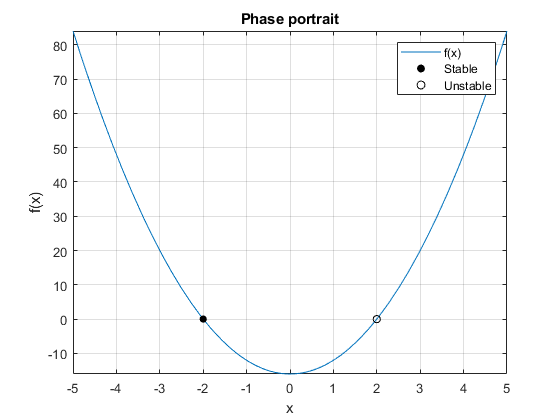


figure()
fplot(f, "DisplayName", "f(x)")
hold on;
grid on;

for i = 1:size(eq_points,1)
    if subs(diff(f), x, eq_points(i)) < 0
        scatter(eq_points(i), vpa(subs(f, x, eq_points(i))), 30,'k', 'filled', 'DisplayName', 'Stable')
    else
        scatter(eq_points(i), vpa(subs(f, x, eq_points(i))), 30,'k', 'DisplayName', 'Unstable')
    end
end
xlabel("x");
ylabel("f(x)")
title("Phase portrait")
legend()

### 1-2 $\dot{\;x} =x-x^3$

syms x

f = x - x^3;

sol = solve(f==0);
eq_points = sol

$$eq\_points = \left(\begin{array}{c} -1\\ 0\\ 1 \end{array}\right)$$

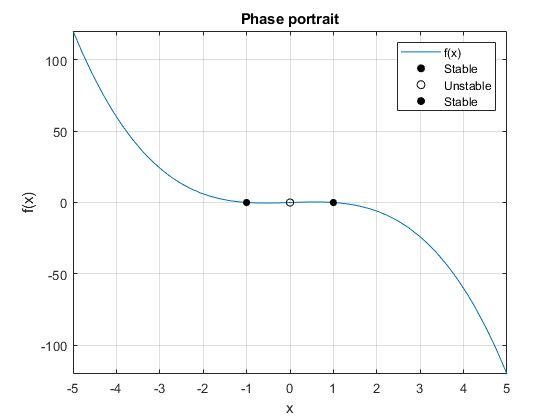


figure()
fplot(f, "DisplayName", "f(x)")
hold on;
grid on;

for i = 1:size(eq_points,1)
    if subs(diff(f), x, eq_points(i)) < 0
        scatter(eq_points(i), vpa(subs(f, x, eq_points(i))), 30,'k', 'filled', 'DisplayName', 'Stable')
    else
        scatter(eq_points(i), vpa(subs(f, x, eq_points(i))), 30,'k', 'DisplayName', 'Unstable')
    end
end
xlabel("x");
ylabel("f(x)")
title("Phase portrait")
legend()

### 1-3 $\dot{\;x} \;=1+\frac{1}{2}\cos \left(x\right)$

syms x

f = 1+0.5*cos(x);

sol = solve(f==0, 'real', true);
eq_points = sol

 
eq_points =
 
Empty sym: 0-by-1
 


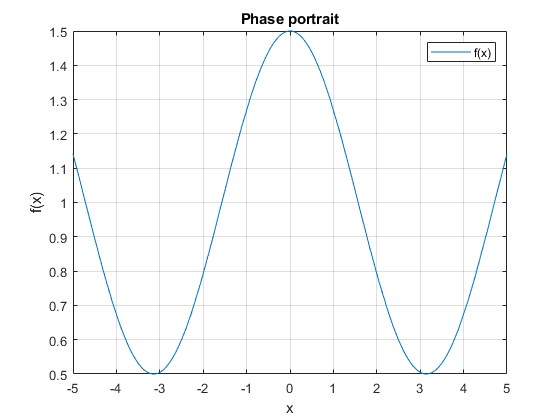


figure()
fplot(f, "DisplayName", "f(x)")
hold on;
grid on;

for i = 1:size(eq_points,1)
    if subs(diff(f), x, eq_points(i)) < 0
        scatter(eq_points(i), vpa(subs(f, x, eq_points(i))), 30,'k', 'filled', 'DisplayName', 'Stable')
    else
        scatter(eq_points(i), vpa(subs(f, x, eq_points(i))), 30,'k', 'DisplayName', 'Unstable')
    end
end
xlabel("x");
ylabel("f(x)")
title("Phase portrait")
legend()

***Note:*** 1-3 does** NOT **have any stability points as it never crosses $f\left(x\right)=0$

### 1-4 $\dot{\;x} =e^{-x} \sin \left(x\right)$

syms x

f = exp(-x)*sin(x)

$$f = {\mathrm{e}}^{-x}\,\sin\left(x\right)$$


sol = solve(f==0, 'real', true, 'returnconditions', true);
eq_points = sol.x

$$eq\_points = \pi \,k$$

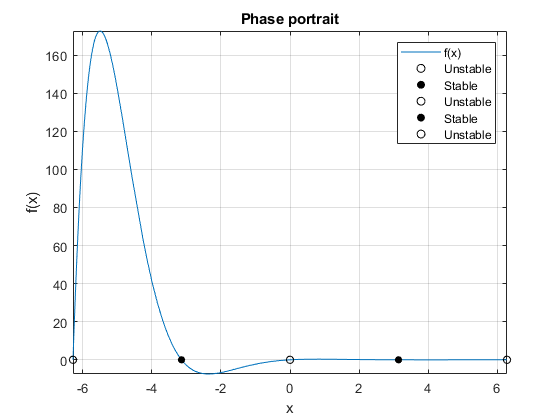


figure()
fplot(f, "DisplayName", "f(x)")
hold on;
grid on;

for i = -2:2
    point = subs(eq_points, k, i);
    if subs(diff(f), x, point) < 0
        scatter(point, vpa(subs(f, x, point)), 30,'k', 'filled', 'DisplayName', 'Stable')
    else
        scatter(point, vpa(subs(f, x, point)), 30,'k', 'DisplayName', 'Unstable')
    end
end
xlabel("x");
ylabel("f(x)")
title("Phase portrait")
legend()

$f\left(x\right)$has an infinite number of eq points at $x=k\pi \;$, alternating between stable and unstable where $x=0$ is unstable

## Problem 2

## Problem 3


$$\dot{\;x} =\sigma \;\left(y-x\right)$$
    
$$\dot{\;y} =\mathrm{rx}-y-\mathrm{xz}$$
    
$$\dot{\;z} =\mathrm{xy}-\mathrm{bz}$$


### 3-1 Find the equilibrium points

syms x y z s r b

X = [x;y;z];
f = [s*(y-x); r*x-y-x*z; x*y-b*z];

sol = solve(f==0, X);
eq_points = [sol.x, sol.y, sol.z]

$$eq\_points = \left(\begin{array}{ccc} 0 & 0 & 0\\ -\sqrt{b\,\left(r-1\right)} & -\sqrt{b\,\left(r-1\right)} & r-1\\ \sqrt{b\,\left(r-1\right)} & \sqrt{b\,\left(r-1\right)} & r-1 \end{array}\right)$$

### 3-2 Linearize the dynamics about the eq points

jac = jacobian(f,X);

#### 3-2-1 $r\le 1$ and $b,\sigma >0$

eigs = cell(3,1);

for i = 1:3
    eigs{i,1} = eig(subs(jac, X, eq_points(i,:)'));
    eigs{i,1} = subs(eigs{i,1}, [r,b,s], [0,1,1]);
    vpa(eigs{i,1},2)
end

$$ans = \left(\begin{array}{c} -1.0\\ -1.0\\ -1.0 \end{array}\right)$$

$$ans = \left(\begin{array}{c} 0.62+1.5e-11\,\mathrm{i}\\ -1.6-7.3e-12\,\mathrm{i}\\ -2.0-7.3e-12\,\mathrm{i} \end{array}\right)$$

$$ans = \left(\begin{array}{c} 0.62+1.5e-11\,\mathrm{i}\\ -1.6-7.3e-12\,\mathrm{i}\\ -2.0-7.3e-12\,\mathrm{i} \end{array}\right)$$

$\mathbb{R}\{\lambda_1\} < 0$, so it is **stable**.

$\mathbb{R}\{\lambda_2\}$ contains both positive & negative values, so it is **unstable**. $\mathbb{I}\{\lambda_2\}$ is negligible.

$\mathbb{R}\{\lambda_3\}$ contains both positive & negative values, so it is **unstable**. $\mathbb{I}\{\lambda_3\}$ is negligible.

#### 3-2-2 $r>1$ and $b,\sigma >0$ where $\sigma >b+1$

for i = 1:3
    eigs{i,1} = eig(subs(jac, X, eq_points(i,:)'));
    eigs{i,1} = subs(eigs{i,1}, [r,b,s], [2,3,5]);
    vpa(eigs{i,1},2)
end

$$ans = \left(\begin{array}{c} -3.0\\ -6.7\\ 0.74 \end{array}\right)$$

$$ans = \left(\begin{array}{c} -1.3-1.7\,\mathrm{i}\\ -1.3+1.7\,\mathrm{i}\\ -6.5-2.3e-10\,\mathrm{i} \end{array}\right)$$

$$ans = \left(\begin{array}{c} -1.3-1.7\,\mathrm{i}\\ -1.3+1.7\,\mathrm{i}\\ -6.5-2.3e-10\,\mathrm{i} \end{array}\right)$$

$\mathbb{R}\{\lambda_1\}$ contains both positive & negaitve values, so it is **unstable**.

$\mathbb{R}\{\lambda_2\} < 0$ and $\mathbb{I}\{\lambda_2\}$ contains both positive & negative values, so it is a **stable spiral**.

$\mathbb{R}\{\lambda_3\} < 0$ and $\mathbb{I}\{\lambda_3\}$ contains both positive & negaitve values, so it is a **stable spiral**.

## Problem 4

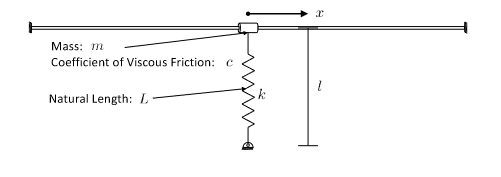


$$m = 1kg$$
    
$$b =0.1Nsm^{-1}$$
    
$$k=1Nm^{-1}$$
    
$$L=1m$$


### 4-1 Derive equations of motion wrt x

Newtons 2nd: $m\ddot{x} = \sum_{i}F_i$

Def: $d = \sqrt{x^2+l^2}$ (spring distance)

Derive forces:

- Spring force: $f_s = -k(d-x)$

-     Along x-axis: $f_s^{(x)} = -k(d-L)sin(\theta) = -k(d-L)\frac{x}{d} = -kx\left(1-\frac{L}{d}\right)$

- Friction force: $f_f^{(x)} = -c\dot{x}$

Equation of motion:

- 
$$m\ddot{x} + c\dot{x} + kx\left(1-\frac{L}{d}\right)=0$$


Statespace form:

- 
$$x=\left\lbrack \begin{array}{c}
x_1 \\
x_2 
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
x\\
\dot{x} 
\end{array}\right\rbrack$$
    

- 
$$f\left(t,x\right)=\dot{x} =\left\lbrack \begin{array}{c}
x_2 \\
-\frac{{\mathrm{cx}}_2 +{\mathrm{kx}}_1 \left(1-\frac{L}{\sqrt{x_1^2 +l^2 }}\right)}{m}
\end{array}\right\rbrack$$


### 4-2 Show the system undergoes a supercritical pitchfork bifurcation at r=0

Rewrite state space in terms of $r = l-L$


$$f\left(t,x\right)=\left\lbrack \begin{array}{c}
x_2 \\
-\frac{{\mathrm{cx}}_2 +{\mathrm{kx}}_1 \left(1-\frac{L}{\sqrt{x_1^2 +{\left(r+L\right)}^2 }}\right)}{m}
\end{array}\right\rbrack$$


syms x1 x2 c k m L r

x = [x1;x2];
f = [x2;-(c*x2+k*x1*(1-L/sqrt(x1^2+(r+L)^2)))/m];
f = subs(f, [c,k,m,L], [0.1,1,1,1]);

eq_points = solve(f==0, x, 'ReturnConditions', true);
eq_points = [eq_points.x1, eq_points.x2]

$$eq\_points = \left(\begin{array}{cc} 0 & 0\\ \sqrt{-r\,\left(r+2\right)} & 0\\ -\sqrt{-r\,\left(r+2\right)} & 0 \end{array}\right)$$

1st eq. point ([0,0]) is always valid.

2nd & 3rd eq. points only valid on $r\in (-2,0)$

**This implies a pitchfork bifurcation**

Now, must determine whether this is super- or sub- critical

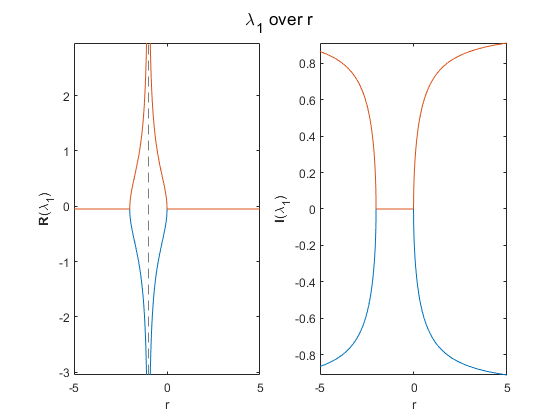

jac = jacobian(f,x);
eig1 = eig(subs(jac, x, eq_points(1,:)'));
figure()
sgtitle("\lambda_1 over r")

subplot(1,2,1)
fplot(real(eig1), [-5,5])
xlabel("r")
ylabel("\bf{R}\rm(\lambda_1)")

subplot(1,2,2)
fplot(imag(eig1), [-5,5])
xlabel("r")
ylabel("\bf{I}\rm(\lambda_1)")

$\mathbb{R}\{\lambda_1(r), r\in (-2,0)\}$contains both a positive and negative component while $\mathbb{I}\{\lambda_1(r), r\in (-2,0)\} = 0$. **This is a saddle point - not stable.**

$\mathbb{I}\{\lambda_1(r), r\in (0,5)\}$ contains both a positive and negative component while $\mathbb{R}\{\lambda_1(r), r\in (0,5)\} = 0$.     **This is a stable focus - stable.**

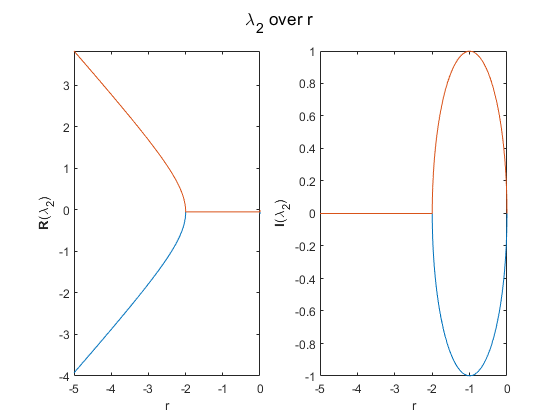

eig2 = eig(subs(jac, x, eq_points(2,:)'));
figure()
sgtitle("\lambda_2 over r")

subplot(1,2,1)
fplot(real(eig2), [-5,0])
xlabel("r")
ylabel("\bf{R}\rm(\lambda_2)")

subplot(1,2,2)
fplot(imag(eig2), [-5,0])
xlabel("r")
ylabel("\bf{I}\rm(\lambda_2)")

$\mathbb{R}\{\lambda_2(r), r\in (-2,0)\} = 0$ while $\mathbb{I}\{\lambda_2(r), r\in (-2,0)\}$contains both positive and negative components. **This is a stable focus - stable.**

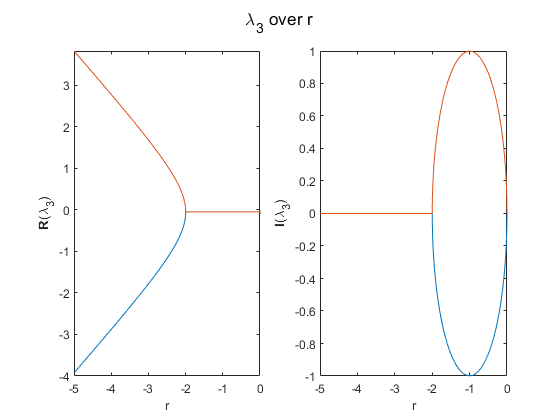

eig3 = eig(subs(jac, x, eq_points(3,:)'));
figure()
sgtitle("\lambda_3 over r")

subplot(1,2,1)
fplot(real(eig3), [-5,0])
xlabel("r")
ylabel("\bf{R}\rm(\lambda_3)")

subplot(1,2,2)
fplot(imag(eig3), [-5,0])
xlabel("r")
ylabel("\bf{I}\rm(\lambda_3)")

$\mathbb{R}\{\lambda_3(r), r\in (-2,0)\} = 0$ while $\mathbb{I}\{\lambda_3(r), r\in (-2,0)\}$contains both positive and negative components. **This is a stable focus - stable.**

**Summary:**

- $\lambda {\;}_1$is unstable on $r\in \left(-2,0\right)$ & stable on $r\in \left(0,2\right)$

- $\lambda_{2,3}$ are stable on $r\in \left(-2,0\right)$ & DNE on $r\in \left(0,2\right)$

- Thus, there exists a supercritical pitchfork bifurcation at $r=0$.

### 4-3 Plot the bifurcation on $r\in \left\lbrack -\frac{1}{2},\frac{1}{2}\right\rbrack$

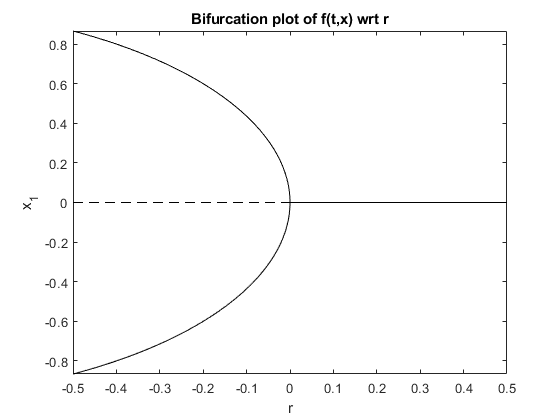

figure()

fplot(eq_points(1,1), [-0.5,0], '--k')
hold on;
fplot(eq_points(2:3,1), [-0.5,0], '-k')
fplot(eq_points(1,1), [0,0.5], '-k')
title("Bifurcation plot of f(t,x) wrt r")
xlabel("r")
ylabel("x_1")

Note that $x_2$ is always stable at 0